Interface01NEuler

Teste da função NEuler com exemplo da sebenta de AM2


$$y'=y+e^{3t}, \quad t \in [1,1.5], \quad y(1)=2, \quad \text{com } n=2$$


Arménio Correia | armenioc@isec.pt

aula04T | 05/03/2024

Metedos numericos para EDO

       | y' = f(t,y)             | y' = y+e^3t

PVI | t € [a,b]        <=> | t € [1, 1.5]     com n=2

       | y(a)=y0               | y(1)=2  

passo h=(b-a)/n

formula yi+1 = yi + h * f(,y1)

clear

% Dados
% help function_handle
strF = "y+exp(3*t)"

strF = "y+exp(3*t)"

f = @(t,y) eval(vectorize(strF)) % vectorize coloca . antes de todas as *

f = function_handle with value:
    @(t,y)eval(vectorize(strF))


% f(1,1)
a = 1

a = 1

b = 1.5

b = 1.5000

n = 5

n = 5

y0 = 2

y0 = 2


% solução exata do problema
syms y(t)
sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

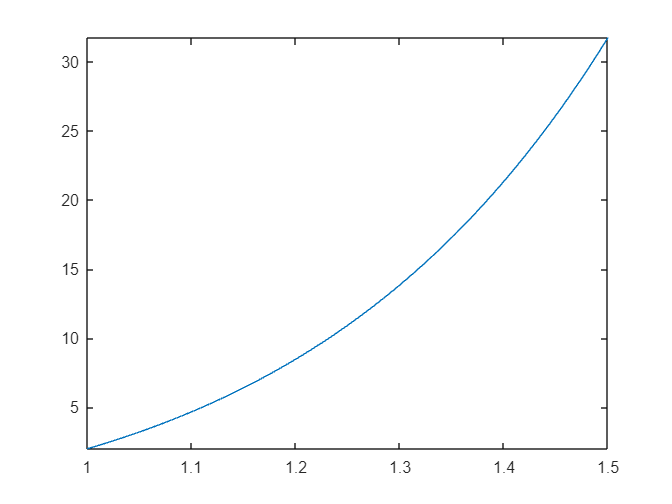

% gráfico da solução exata no intervalo [a,b]
fplot(sExata,[a,b])

% solução exata do problema (expressão numérica)
g = @(t) eval(vectorize(char(sExata)));

% resultados e tabela de resultados
[t,yEuler] = NEuler_v01(f,a,b,n,y0);
yExata = g(t);
erroEuler = abs(yExata-yEuler);
A = [t.',yExata.',yEuler.',erroEuler.'];
tabelaResultados = array2table(A,"VariableNames", ...
                   ["t","Exata","Euler","erroEuler"])

tabelaResultados = 6×4 table
     t     Exata     Euler     erroEuler
    ___    ______    ______    _________

      1         2         2           0 
    1.1    4.6677    4.2086     0.45913 
    1.2    8.4757    7.3407       1.135 
    1.3    13.845    11.735      2.1101 
    1.4    21.345    17.848      3.4965 
    1.5    31.748    26.302      5.4466 


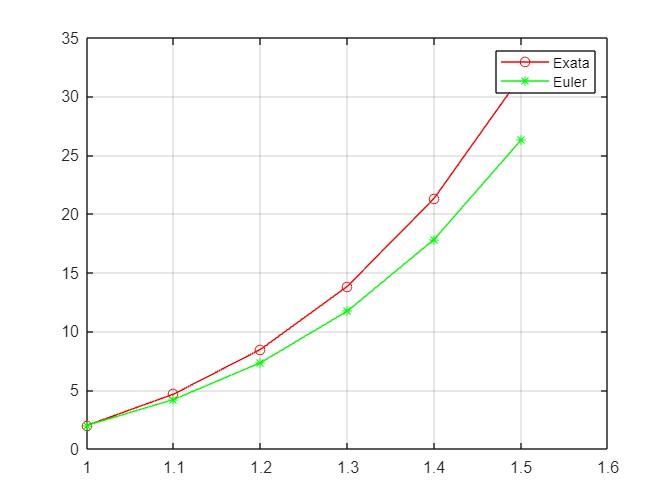


% representacao gráfica
plot(t,yExata,"-ro")
hold on
% fplot(sExata,[a,b],"b")
plot(t,yEuler,"-g*")
hold off
grid on
legend('Exata','Euler')